clear all
close all

addpath("Immagini\05_slantedEdge")
addpath("Immagini\06_binning")

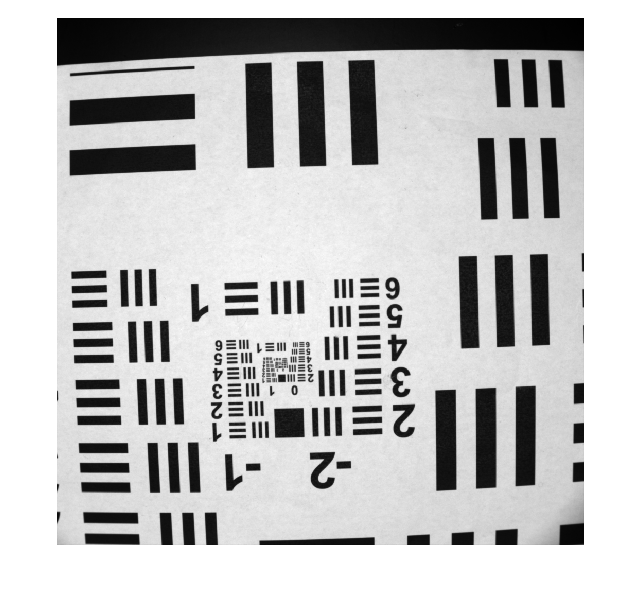

im_1 = importdata("Risoluzione_B1_t2_f4.asc");
im_1 = im_1(:,2:end);

noise_1 = importdata("Risoluzione_buio_B1_t2_f4.asc");
noise_1 = noise_1(:,2:end);

im_1 = im_1 - noise_1;

imshow(im_1,[])

R = [];

for i=-2:1:1
    for j=1:1:6
        R = [R; i j 2^(i+(j-1)/6)];
    end
end

MTF_fun = @(x) (max(x)-min(x))/(max(x)+min(x));

I_m2 = improfile(im_1, [607 607], [500 820]);

I_m21 = improfile(im_1, [360 360], [510 585]);
M_m21 = MTF_fun(I_m21(4:70));

I_m22 = I_m2(253:313);
M_m22 = MTF_fun(I_m22);

I_m23 = I_m2(182:234);
M_m23 = MTF_fun(I_m23);

I_m24 = I_m2(117:164);
M_m24 = MTF_fun(I_m24);

I_m25 = I_m2(59:101);
M_m25 = MTF_fun(I_m25);

I_m26 = I_m2(7:45);
M_m26 = MTF_fun(I_m26);

I_m1 = improfile(im_1, [340 340], [620 825]);

I_m11 = I_m1(166:200);
M_m11 = MTF_fun(I_m11);

I_m12 = I_m1(127:157);
M_m12 = MTF_fun(I_m12);

I_m13 = I_m1(92:118);
M_m13 = MTF_fun(I_m13);

I_m14 = I_m1(60:84);
M_m14 = MTF_fun(I_m14);

I_m15 = I_m1(32:54);
M_m15 = MTF_fun(I_m15);

I_m16 = I_m1(7:26);
M_m16 = MTF_fun(I_m16);

I_0 = improfile(im_1, [476 476], [620 710]);

I_01 = improfile(im_1, [414 414], [630 650]);
M_01 = MTF_fun(I_01(2:20));

I_02 = I_0(73:88);
M_02 = MTF_fun(I_02);

I_03 = I_0(55:68);
M_03 = MTF_fun(I_03);

I_04 = I_0(39:50);
M_04 = MTF_fun(I_04);

I_05 = I_0(24:34);
M_05 = MTF_fun(I_05);

I_06 = I_0(12:20);
M_06 = MTF_fun(I_06);

I_1 = improfile(im_1, [410 410], [655 710]);

I_11 = I_1(47:54);
M_11 = MTF_fun(I_11);

I_12 = I_1(37:43);
M_12 = MTF_fun(I_12);

I_13 = I_1(28:33);
M_13 = MTF_fun(I_13);

I_14 = I_1(20:25);
M_14 = MTF_fun(I_14);

% plot(I_1)

I_min = min(im_1(250:280, 480:510));
I_max = max(im_1(300:330, 480:510));
M_O = (I_max-I_min)/(I_max+I_min);

y = [M_m21 M_m22 M_m23 M_m24 M_m25 M_m26 M_m11 M_m12 M_m13 M_m14 M_m15 M_m16 M_01 M_02 M_03 M_04 M_05 M_06 M_11 M_12 M_13 M_14]./M_O

y =     0.9737    1.0041    0.9978    0.9922    0.9585    0.9600    0.9870    0.9048    0.9393    0.9318    0.9122    0.8851    0.8555    0.7706    0.7003    0.6633    0.5179    0.4542    0.3622    0.2870    0.2391    0.1237


x = R(1:22, 3)

x =     0.2500
    0.2806
    0.3150
    0.3536
    0.3969
    0.4454
    0.5000
    0.5612
    0.6300
    0.7071


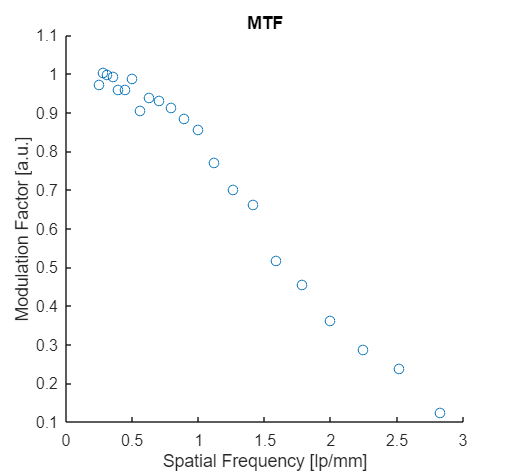


scatter(x,y)
title("MTF")
xlabel("Spatial Frequency [lp/mm]")
ylabel("Modulation Factor [a.u.]")

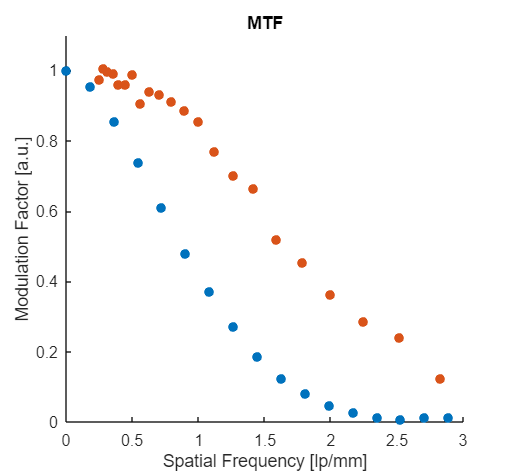

Fiji_MTF = csvread("ImageJ_MTF.csv", 1);
x_1 = Fiji_MTF(:,1)*5.6;
y_1 = Fiji_MTF(:,2);

scatter(x_1, y_1,'filled')
title("MTF")
ylim([0 1.1])
xlim([0 3])
hold on
scatter(x,y,'filled')
hold off
xlabel("Spatial Frequency [lp/mm]")
ylabel("Modulation Factor [a.u.]")

[~,~,R_MTF] = str_line(2.51984,0.239073,2.82843,0.123729);
R_MTF = 1/R_MTF

R_MTF = 0.3810


[~,~,R_FijiMTF] = str_line(1.26451,0.271394,1.44516,0.186272);
R_FijiMTF = 1/R_FijiMTF

R_FijiMTF = 0.7062

function [m, b, x_ext] = str_line(x1, y1, x2, y2)
m = (y2-y1) / (x2-x1);
b = y1 - m*x1;
x_ext = (0.2-b)/m;
end